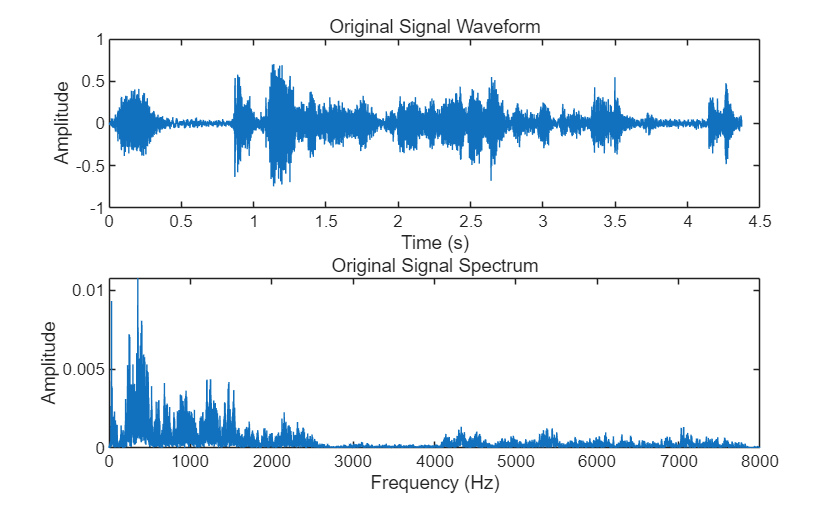

[y1, fs] = audioread("C:\Users\18237\Desktop\2.wav");
y1 = y1(:)'; 


L = length(y1);
t = (0:L-1) / fs;
f = fs * (0:(L/2)) / L; 

N = 4;
f_min = 200;
f_max = 7000;
d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;
d_edges = linspace(d_min, d_max, N + 1);
pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);
d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);


figure;
subplot(2,1,1);
plot(t, y1);
title('Original Signal Waveform');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y1_fft = fft(y1);
P1 = abs(Y1_fft/L); P1_single = P1(1:floor(L/2)+1); P1_single(2:end-1) = 2*P1_single(2:end-1);
plot(f, P1_single);
title('Original Signal Spectrum');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

LPF_cut_freq = 20

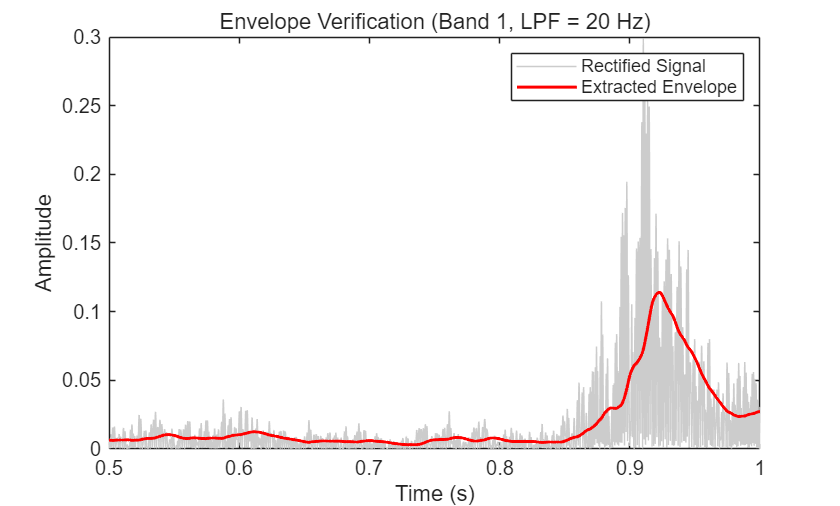


LPF_cut_freq = 20;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);

    if i == 1 
        figure;
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t); 
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_20 = y1_sum * sqrt(e1 / es);

e_final_20 = sum(y1_20.^2);
fprintf('能量验证 LPF = 20Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_20);

能量验证 LPF = 20Hz原始信号能量: 666.6279, 归一化后信号能量: 666.6279


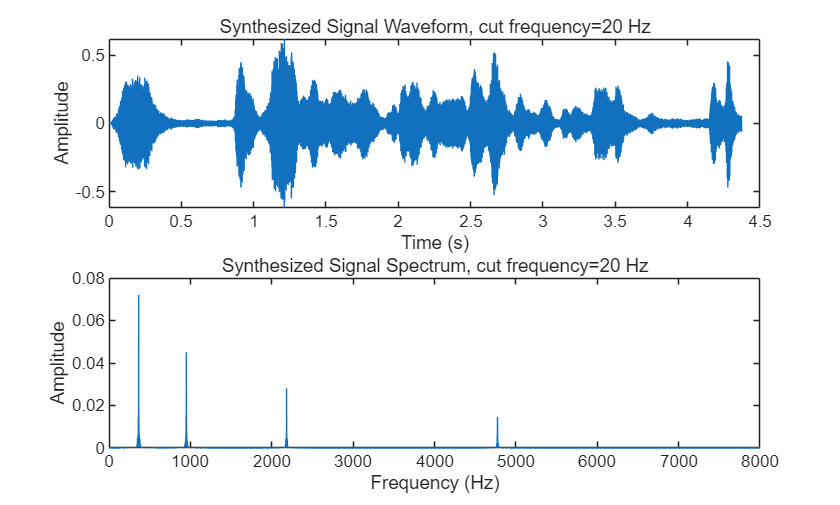


filename = sprintf('Task2_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y1_20, fs);

figure;
subplot(2,1,1);
plot(t, y1_20);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_20);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

LPF_cut_freq = 50

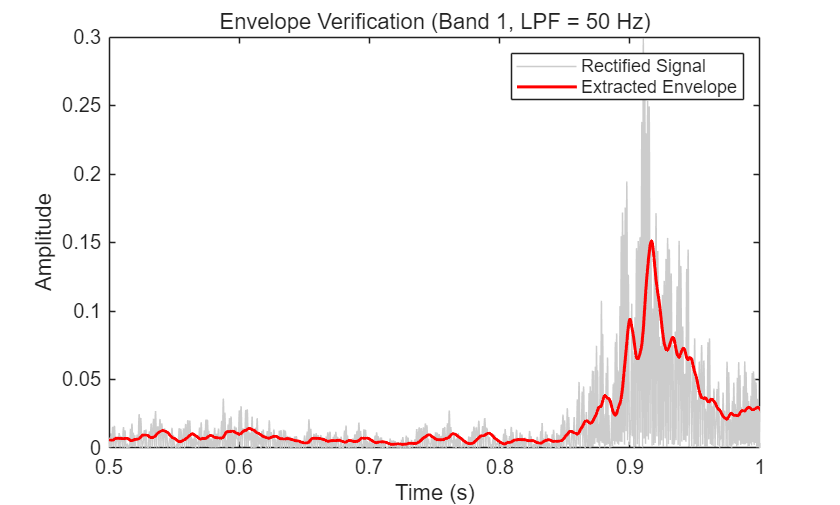

LPF_cut_freq = 50;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);

  
    if i == 1 
        figure;
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_50 = y1_sum * sqrt(e1 / es);
e_final_50 = sum(y1_50.^2);
fprintf('能量验证 LPF = 50Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_50);

能量验证 LPF = 50Hz原始信号能量: 666.6279, 归一化后信号能量: 666.6279


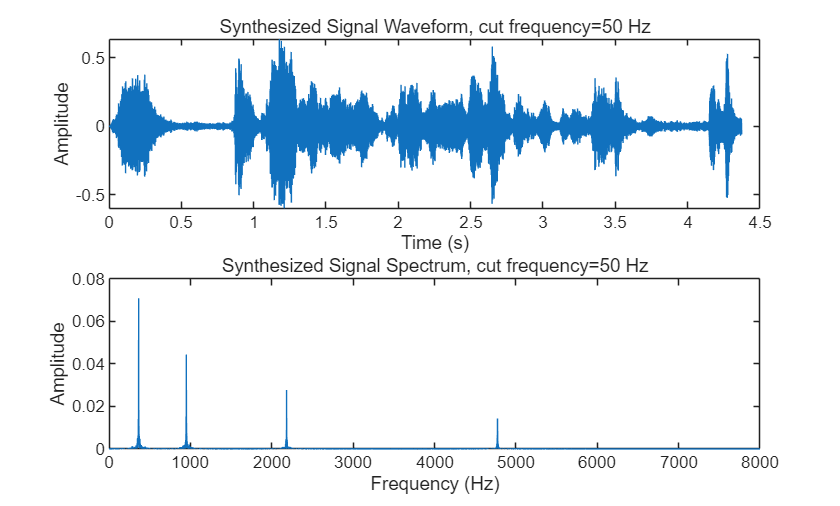


filename = sprintf('Task2_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y1_50, fs);

figure;
subplot(2,1,1);
plot(t, y1_50);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_50);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

LPF_cut_freq = 100

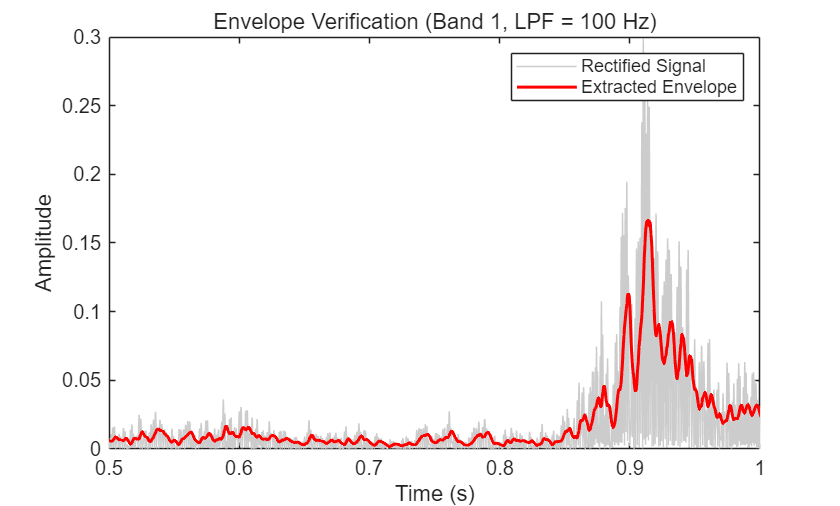

LPF_cut_freq = 100;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);

 
    if i == 1 
        figure;
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_100 = y1_sum * sqrt(e1 / es);
e_final_100 = sum(y1_100.^2);
fprintf('能量验证 LPF = 100Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_100);

能量验证 LPF = 100Hz原始信号能量: 666.6279, 归一化后信号能量: 666.6279


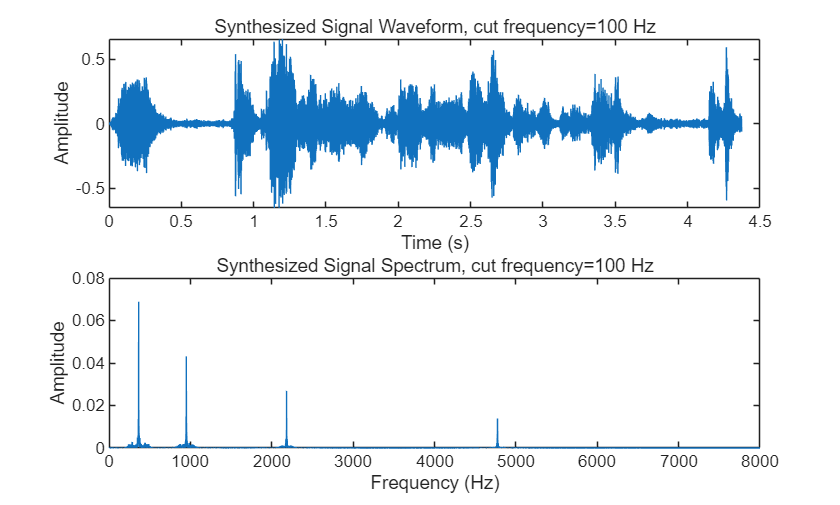


filename = sprintf('Task2_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y1_100, fs);

figure;
subplot(2,1,1);
plot(t, y1_100);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_100);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

LPF_cut_freq = 400

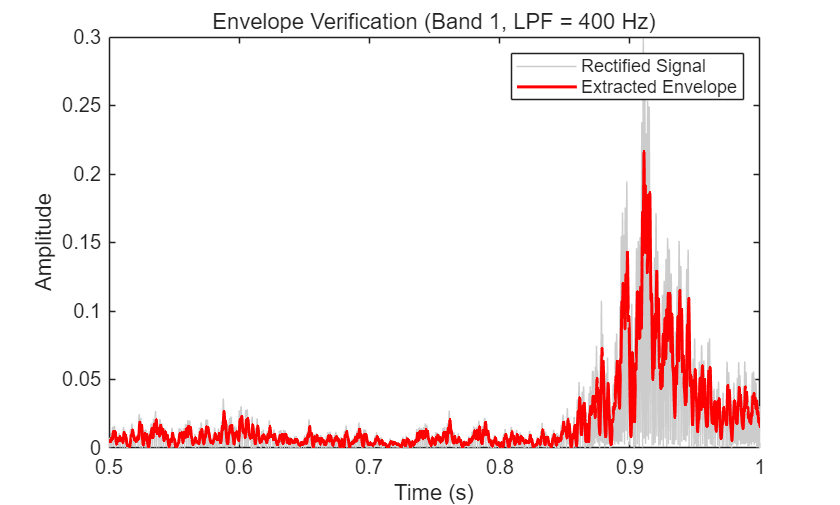

LPF_cut_freq = 400;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);

    % --- 补充：400Hz 包络验证图 ---
    if i == 1 
        figure;
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_400 = y1_sum * sqrt(e1 / es);

e_final_400 = sum(y1_400.^2);
fprintf('能量验证 LPF = 400Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_400);

能量验证 LPF = 400Hz原始信号能量: 666.6279, 归一化后信号能量: 666.6279


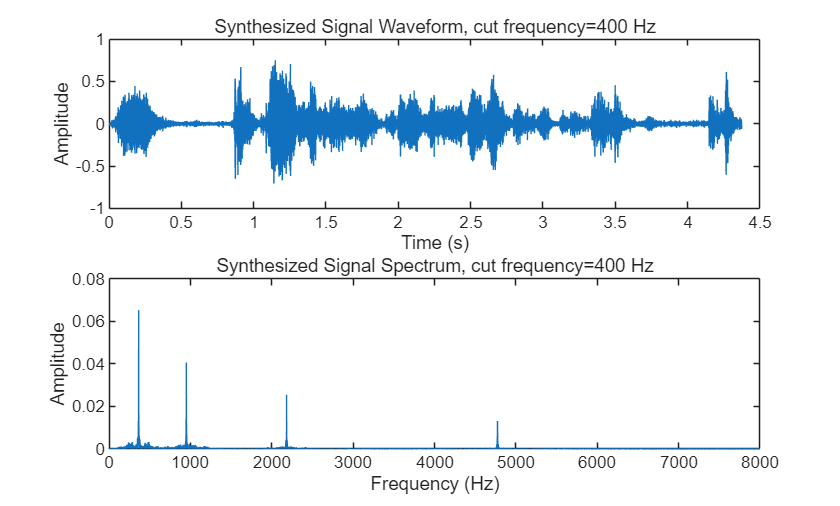


filename = sprintf('Task2_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y1_400, fs);

figure;
subplot(2,1,1);
plot(t, y1_400);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_400);
P = abs(Y_fft/L); %真实振幅 除以L即除以N 求得DTFS
P_single = P(1:floor(L/2)+1); %因为是实信号在频域谱上共轭对称，所以画出一半即可
P_single(2:end-1) = 2*P_single(2:end-1);%因为频域画了一半，所以要把幅度*2 
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

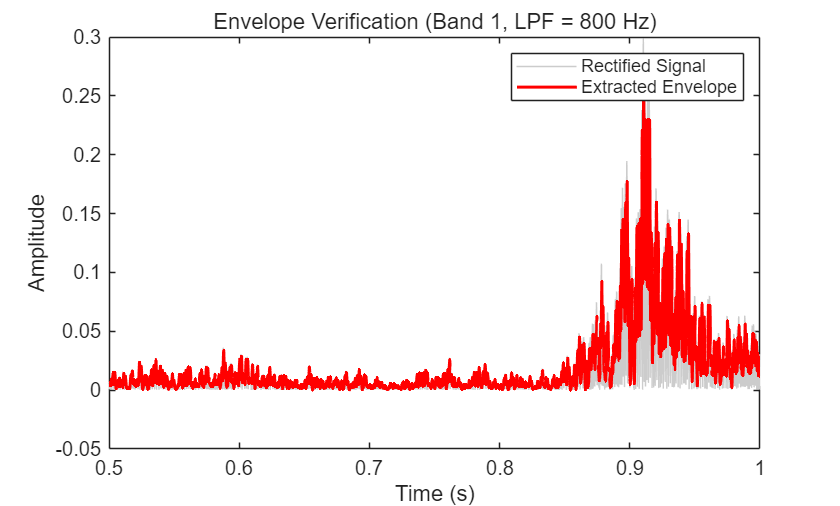

LPF_cut_freq = 800;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2));

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);

    % --- 补充：400Hz 包络验证图 ---
    if i == 1 
        figure;
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (Band 1, LPF = %d Hz)', LPF_cut_freq));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_400 = y1_sum * sqrt(e1 / es);

e_final_400 = sum(y1_400.^2);
fprintf('能量验证 LPF = 400Hz原始信号能量: %.4f, 归一化后信号能量: %.4f\n', e1, e_final_400);

能量验证 LPF = 400Hz原始信号能量: 666.6279, 归一化后信号能量: 666.6279


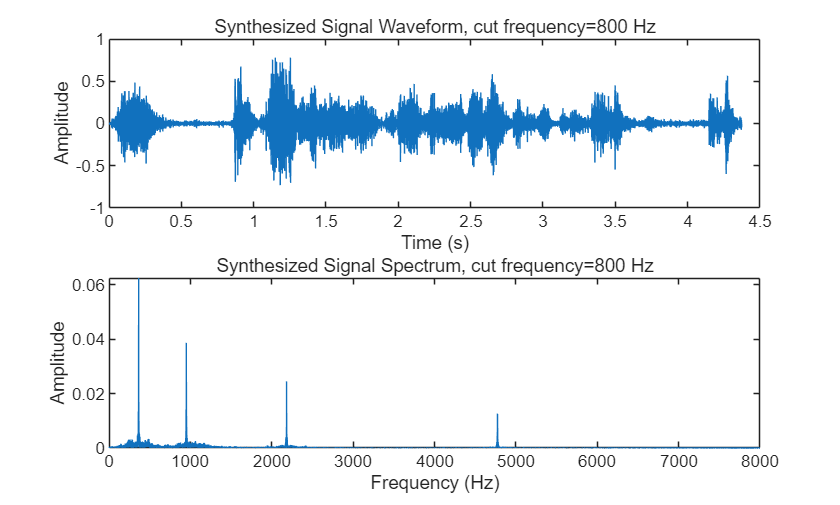


filename = sprintf('Task2_LPF_cut_freq%d.wav', LPF_cut_freq);
audiowrite(filename, y1_400, fs);

figure;
subplot(2,1,1);
plot(t, y1_400);
title(sprintf('Synthesized Signal Waveform, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_400);
P = abs(Y_fft/L); %真实振幅 除以L即除以N 求得DTFS
P_single = P(1:floor(L/2)+1); %因为是实信号在频域谱上共轭对称，所以画出一半即可
P_single(2:end-1) = 2*P_single(2:end-1);%因为频域画了一半，所以要把幅度*2 
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, cut frequency=%d Hz', LPF_cut_freq));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

task2_files = {
    'Task2_LPF_cut_freq20.wav'
    'Task2_LPF_cut_freq50.wav'
    'Task2_LPF_cut_freq100.wav'
    'Task2_LPF_cut_freq800.wav'
};

task2_names = {
    'Task 2 - LPF cutoff = 20 Hz'
    'Task 2 - LPF cutoff = 50 Hz'
    'Task 2 - LPF cutoff = 100 Hz'
    'Task 2 - LPF cutoff = 800 Hz'
};

for k = 1:length(task2_files)

    if ~isfile(task2_files{k})
        fprintf('File not found: %s\n', task2_files{k});
        continue;
    end

    fprintf('\nPress Enter to play: %s\n', task2_names{k});
    pause;

    [y_play, fs_play] = audioread(task2_files{k});

    if size(y_play, 2) > 1
        y_play = mean(y_play, 2);
    end

    if max(abs(y_play)) > 0
        y_play = y_play / max(abs(y_play));
    end

    fprintf('Now playing: %s\n', task2_names{k});
    player = audioplayer(y_play, fs_play);
    playblocking(player);

end


Press Enter to play: Task 2 - LPF cutoff = 20 Hz


Now playing: Task 2 - LPF cutoff = 20 Hz



Press Enter to play: Task 2 - LPF cutoff = 50 Hz


Now playing: Task 2 - LPF cutoff = 50 Hz



Press Enter to play: Task 2 - LPF cutoff = 100 Hz


Now playing: Task 2 - LPF cutoff = 100 Hz



Press Enter to play: Task 2 - LPF cutoff = 800 Hz


Now playing: Task 2 - LPF cutoff = 800 Hz
